 
 Iteration   Func-count     min f(x)         Procedure
     0            1           674082         
     1            4           660399         initial simplex
     2            6           652375         expand
     3            8           640769         expand
     4           10           617182         expand
     5           12           595101         expand
     6           14           553494         expand
     7           16           501350         expand
     8           18           445996         expand
     9           20           356435         expand
    10           22           280553         expand
    11           24           187340         expand
    12           26           165619         reflect
    13           28           122705         reflect
    14           30           122705         contract inside
    15           32           122705         contract inside
    16           33           122705         reflect
    17           35           12270

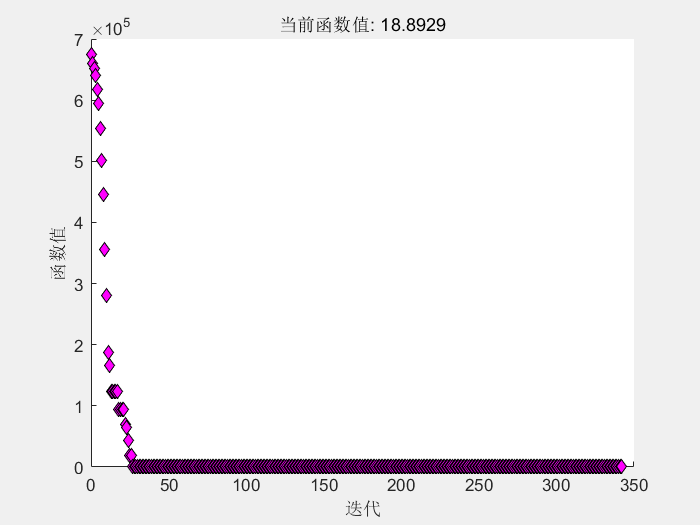

 
正在退出: 超过了函数计算的最大数目
 - 请增大 MaxFunEvals 选项。
 当前函数值: 18.892861 



%% Triple exponential smoothing
% runs holt-winter algorithm
% credits to the fantastic blog post of grisha trubetskoy 
% take a look: https://grisha.org/blog/2016/02/17/triple-exponential-smoothing-forecasting-part-iii/
% still under construction, function can't be optimized
clc
clear all
load("matlab4.mat")
load("matlab5.mat")
%by day
for i = 1:4745
    data(i) = PekingTemp(i);
end
% for i = 1:1380
% clear
% clc
% close all
% 
% data = [30,21,29,31,40,48,53,47,37,39,31,29,17,9,20,24,27,35,41,38,...
%          27,31,27,26,21,13,21,18,33,35,40,36,22,24,21,20,17,14,17,19,...
%          26,29,40,31,20,24,18,26,17,9,17,21,28,32,46,33,23,28,22,27,...
%          18,8,17,21,31,34,44,38,31,30,26,32]; %example data set used by g. trubetskoy

n_year=13; %length of data set
n_predYear = 4;%length of pred data
slen=365; %seasonal length


b0=[];
for i=1:slen
    b0=[b0 (data(i+slen)-data(i))/slen];
end
b0=sum(b0)/slen; % initial trend, here average of trend across seasons

ap=[];
for j=1:n_year
    ap=[ap sum(data(slen*(j-1)+1:slen*j))/slen];
end % averages of each year

ym=zeros(slen,n_year);
for j=1:n_year
    for i=1:slen
        ym(i,j)=data(i+(j-1)*slen)/ap(j);
    end
end % division by appropriate yearly mean
I=[];
for i=1:slen
        I=[I sum(ym(i,:))/n_year];
end % initial seasonal components

n_pred=slen*n_predYear; %forecasting period


% alpha=0.05;
% beta=0.05;
% gamma=0.05;

alpha=0.00005;
beta=0.05;
gamma=0.05;

p=[alpha beta gamma]; %calibration parameters
X0=[p data n_pred b0 I slen]; %initial values
    
options.Display='iter';
options.FunValCheck='on';
options.PlotFcns=@optimplotfval;
numbruns=200*length(p);
options.MaxFunEvals=numbruns;
options.MaxIter=numbruns;

minFunc = @(p)holtwinters(p,data,n_pred,b0,I,slen);
[x,fval,exitflag,output]=fminsearch(minFunc,p,options);


[ee,ts]=holtwinters(x,data,n_pred,b0,I,slen);

for i = 4746:6125
    YPredForHW(i-4745) = ts(i);
end

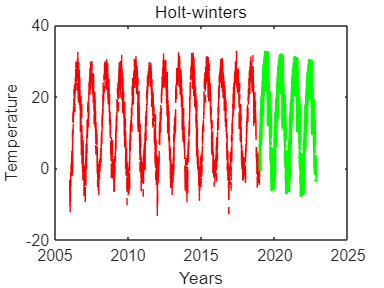

hold off

% visualisation of results

times1 = 2006:(1/365):(2018+364/365);
times2 = 2019:(1/365):(2022+(364-80)/365);
figure(2)
plot(times1,data,'--r')
hold on
plot(times2,YPredForHW,'g','LineWidth',2)
xlabel("Years") ,ylabel("Temperature")
title("Holt-winters")

for i = 4746:6125
    YPred(i-4745) = ts(i);
    YReal(i-4745) = PekingTemp(i);
end
mae = mean(abs(YReal - YPred))

mae = 3.6850

sse = sum((YPred - YReal).^2)

sse = 3.1411e+04

rmse = sqrt(mean((YPred-YReal).^2))

rmse = 4.7709

mape = mean(abs((YReal - YPred)./YReal))*100  

mape = 171.6921